# Three Node Network inversion with TAPAS

## Simulate resting state data for three node network

As done in Frässle et al. (2021) using function created code from SPM's `DEM_demo_induced_fMRI.m `to generate resting state time series.

stim_options = get_default_stim_options()

Generate data using AR(1) process.

DCM = make_DEM_demo_induced_fmri(stim_options);

Make graph object for visualization.

names = {'1' '2' '3'};
tmp = digraph(DCM.Tp.A', names);

Visualize simulated graph and BOLD data.

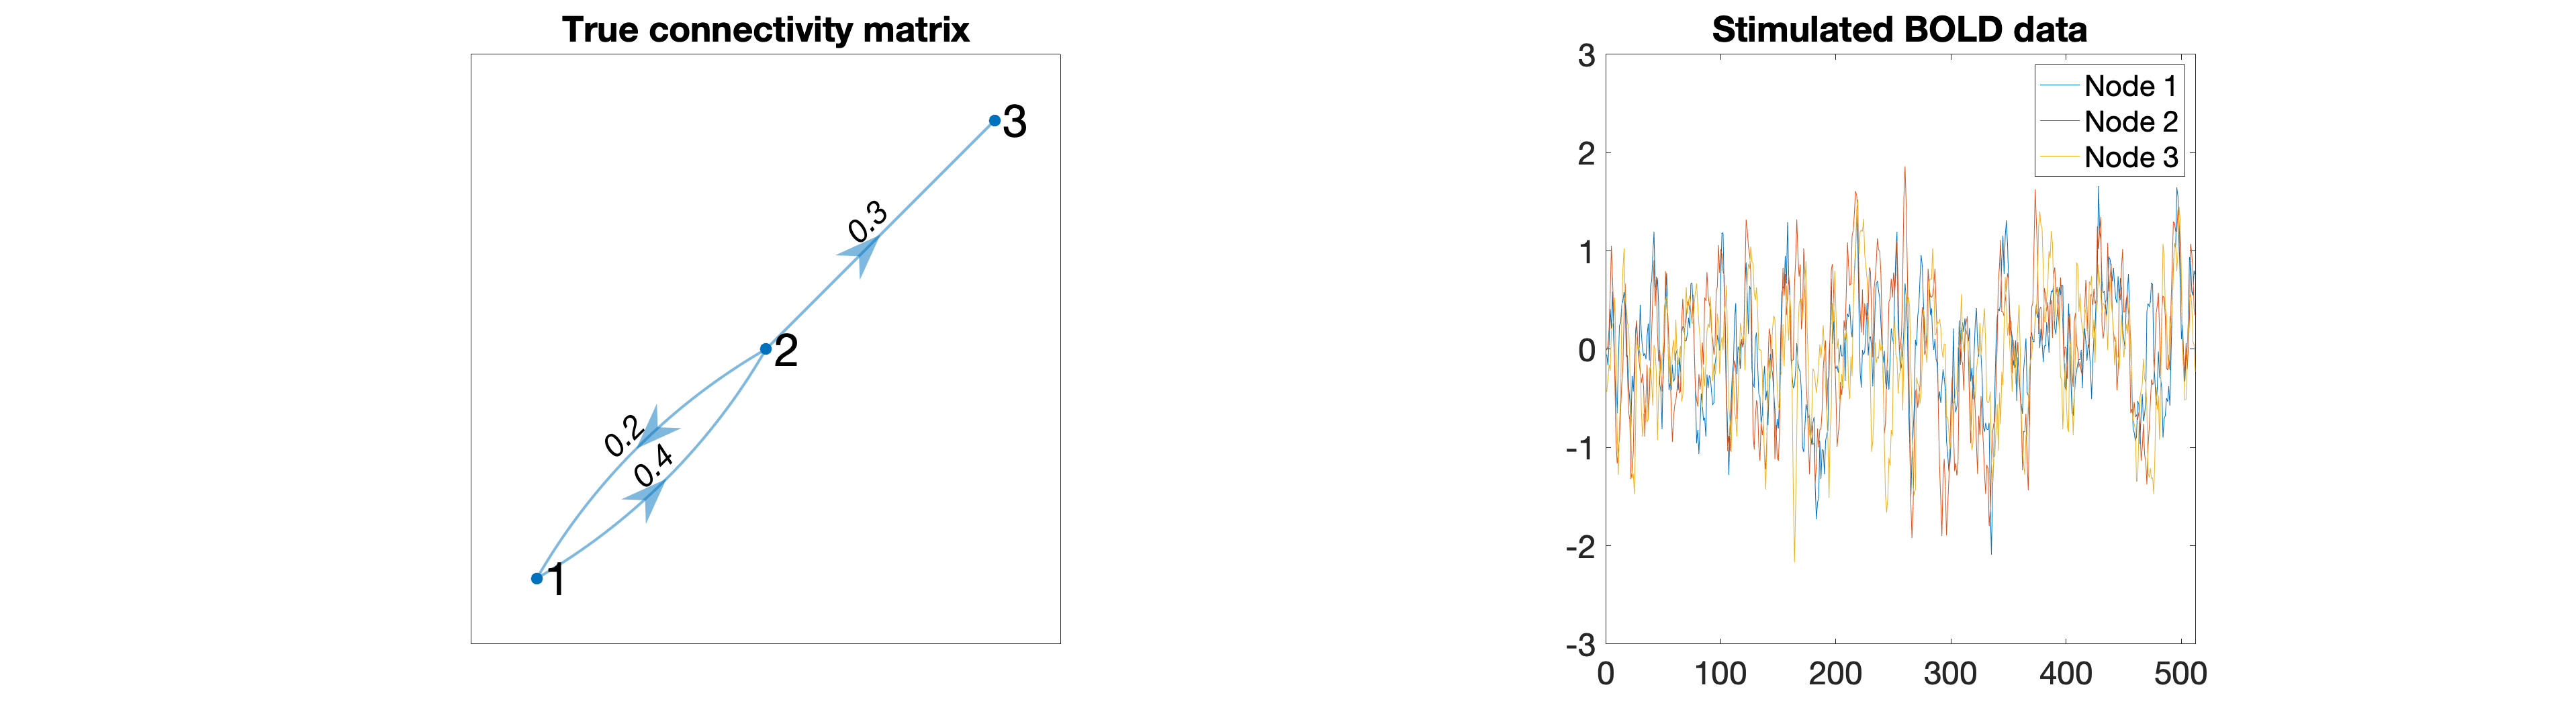

clf
subplot(1, 2, 1)
p = plot(tmp,'Layout','force','EdgeLabel',tmp.Edges.Weight);
title("True connectivity matrix")
axis square
ax = gca;
ax.FontSize = 24;
p.LineWidth = 2;
p.NodeFontSize = 34;
p.EdgeFontSize = 24;
p.ArrowSize = 26;
highlight(p,[1 2 3]);

subplot(1,2,2)
plot(DCM.Y.y);
axis([0 512 -3 3])
title("Stimulated BOLD data");
legend("Node 1", "Node 2", "Node 3")
axis square
ax = gca;
ax.FontSize = 24;

set(gcf,'position',[0,0,400,250]);
set(gcf,'Units','normalized','Position',[0 0 1 .5]);

Specify the options for the rDCM analysis

type = 's';
methods = 1; %1 for ridge, 2 for pruning

Clear workspace before inversion

clearvars -except DCM type options methods

## Invert simulated data

% [output, options] = tapas_rdcm_estimate(DCM, type, options, methods);

What is the recovered connectivity matrix? 

Before removing the AR(1) input it recovered the AR process coefficient of 1/2 but not connectivity.

% output.Ep.A

Remove input so rDCM knows its endogenous activity and set other parameters in the structure that the functions need.

% DCM = rmfield(DCM,'U');
% [output, options] = tapas_rdcm_estimate(DCM, type, options, methods);

So what happens if you change apriori self connectivity to 0?